# Lab 11

### Name: Purval Madhukar Bhude

### Roll No. S20230010193

### Section 4

## Question 1

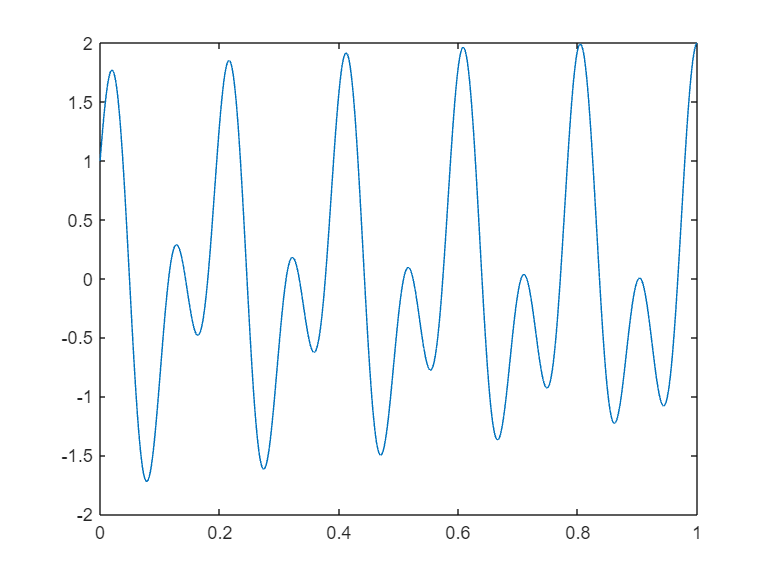

t=0:0.001:1;
xt=sin(20.5*pi*t)+cos(10*pi*t);
figure;
plot(t, xt);

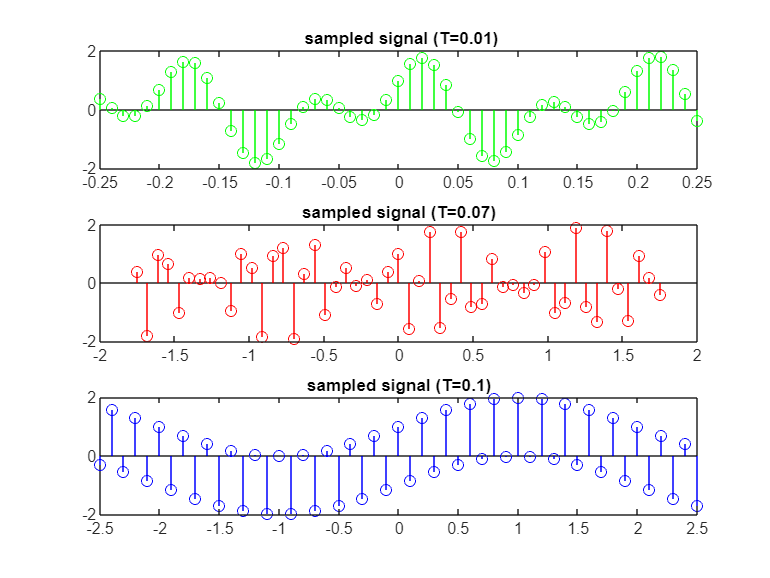

T1=0.01;
T2=0.07;
T3=0.1;
n=-25:1:25;
xnt1=sin(20.5*pi*n*T1)+cos(10*pi*n*T1);
xnt2=sin(20.5*pi*n*T2)+cos(10*pi*n*T2);
xnt3=sin(20.5*pi*n*T3)+cos(10*pi*n*T3);

subplot(3,1,1);
stem(n*T1,xnt1,'g');
title(" sampled signal (T=0.01)");

subplot(3,1,2);
stem(n*T2,xnt2,'r');
title("sampled signal (T=0.07)");

subplot(3,1,3);
stem(n*T3,xnt3,'b');
title("sampled signal (T=0.1)");

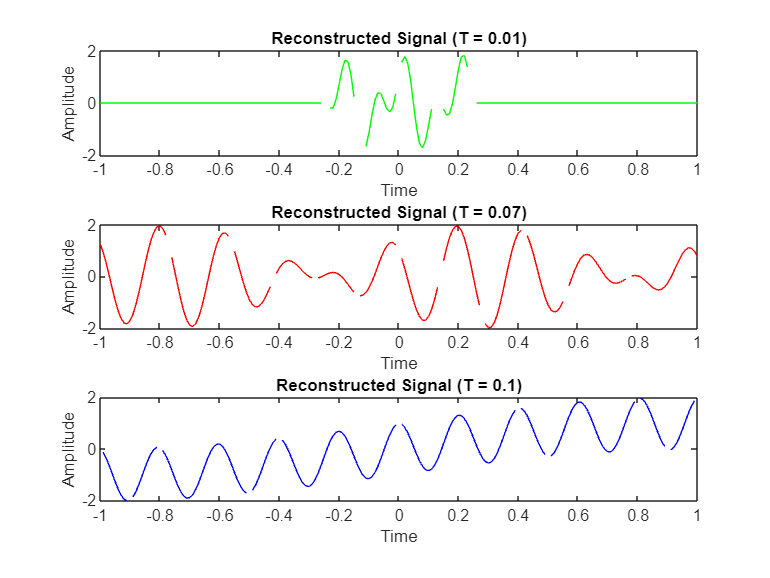

sinc = @(x) sin(pi*x)./(pi*x);

Fs = 100; 

t_ini = -1:1/Fs:1;

xr1 = zeros(size(t_ini));
xr2 = zeros(size(t_ini));
xr3 = zeros(size(t_ini));

for i = 1:length(n)
    xr1 = xr1 + xnt1(i) * sinc((t_ini - n(i)*T1)/T1);% scaled by the sampling time period T1
    xr2 = xr2 + xnt2(i) * sinc((t_ini - n(i)*T2)/T2);
    xr3 = xr3 + xnt3(i) * sinc((t_ini - n(i)*T3)/T3);
end

figure;

subplot(3,1,1);
plot(t_ini, xr1, 'g');
title("Reconstructed Signal (T = 0.01)");
xlabel("Time");
ylabel("Amplitude");

subplot(3,1,2);
plot(t_ini, xr2, 'r');
title("Reconstructed Signal (T = 0.07)");
xlabel("Time");
ylabel("Amplitude");

subplot(3,1,3);
plot(t_ini, xr3, 'b');
title("Reconstructed Signal (T = 0.1)");
xlabel("Time");
ylabel("Amplitude");

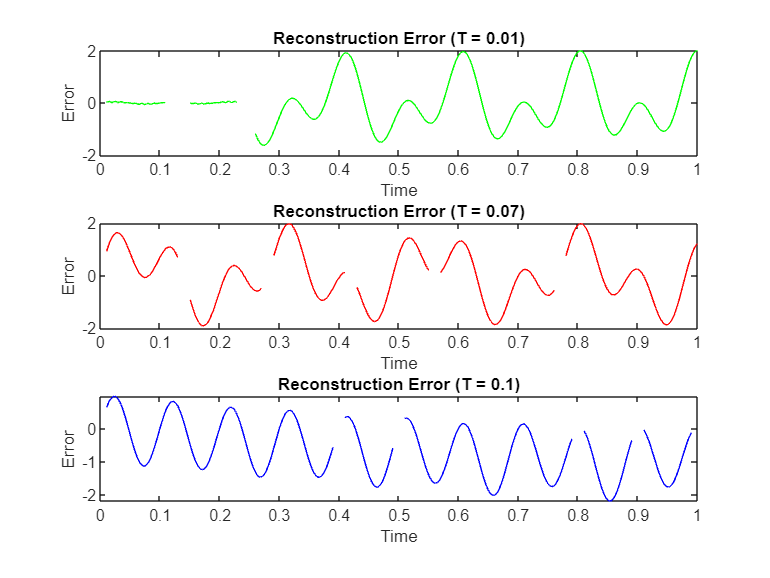

error1 = xt - interp1(t_ini, xr1, t, 'linear', 'extrap');
error2 = xt - interp1(t_ini, xr2, t, 'linear', 'extrap');
error3 = xt - interp1(t_ini, xr3, t, 'linear', 'extrap');

figure;
subplot(3,1,1);
plot(t, error1, 'g');
title("Reconstruction Error (T = 0.01)");
xlabel("Time");
ylabel("Error");

subplot(3,1,2);
plot(t, error2, 'r');
title("Reconstruction Error (T = 0.07)");
xlabel("Time");
ylabel("Error");

subplot(3,1,3);
plot(t, error3, 'b');
title("Reconstruction Error (T = 0.1)");
xlabel("Time");
ylabel("Error");

## Question 2

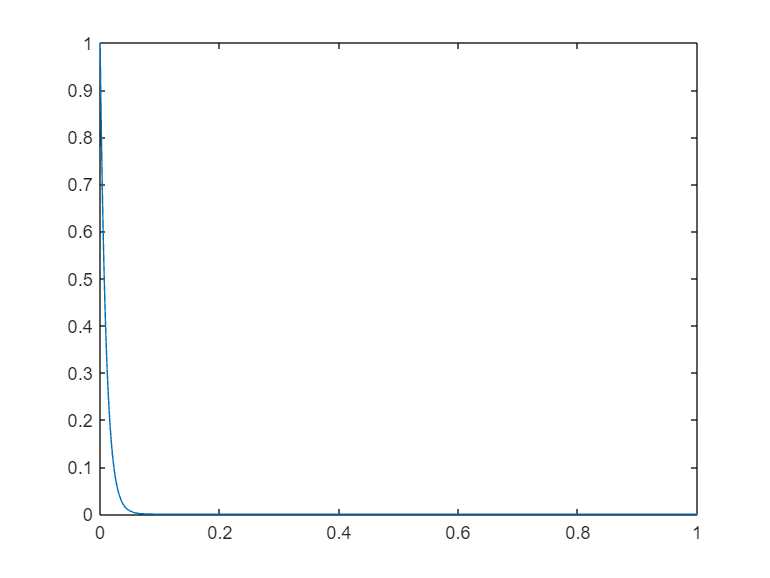

t=0:0.001:1;
xt=exp(-100*abs(t));
figure;
plot(t, xt);

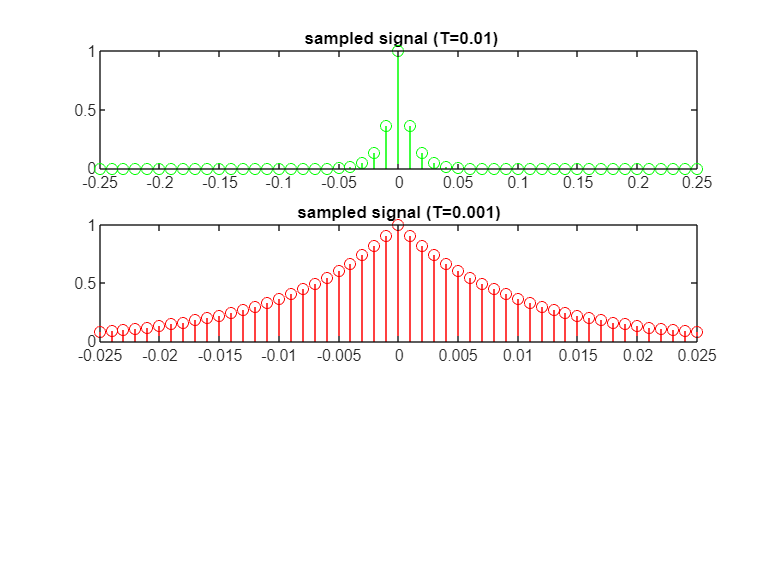

T1=0.01;
T2=0.001;
n=-25:1:25;
xnt1 = exp(-100*abs(n*T1));
xnt2 = exp(-100*abs(n*T2));

subplot(3,1,1);
stem(n*T1,xnt1,'g');
title(" sampled signal (T=0.01)");

subplot(3,1,2);
stem(n*T2,xnt2,'r');
title("sampled signal (T=0.001)");

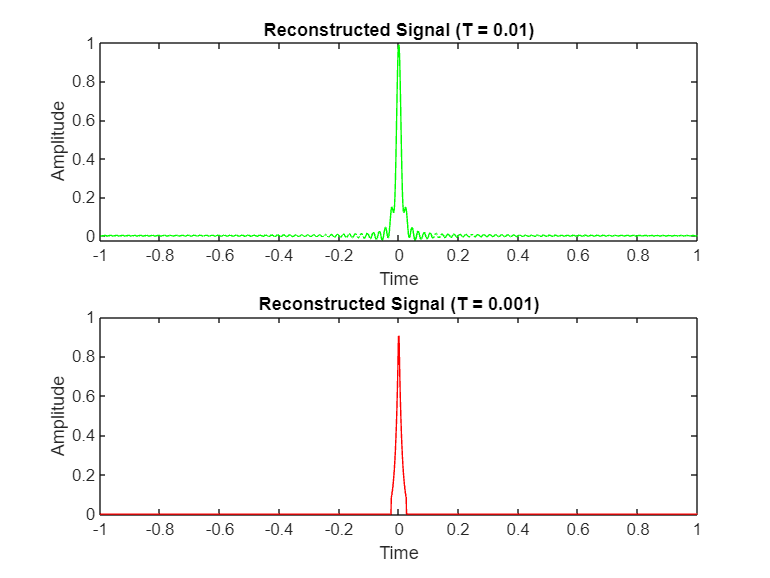

sinc = @(x) sin(pi*x)./(pi*x);

Fs = 1000;

t_ini = -1:1/Fs:1;

xr1 = zeros(size(t_ini));
xr2 = zeros(size(t_ini));

for i = 1:length(n)
    xr1 = xr1 + xnt1(i) * sinc((t_ini - n(i)*T1)/T1);% scaled by the sampling time period T1
    xr2 = xr2 + xnt2(i) * sinc((t_ini - n(i)*T2)/T2);
end

figure;

subplot(2,1,1);
plot(t_ini, xr1, 'g');
title("Reconstructed Signal (T = 0.01)");
xlabel("Time");
ylabel("Amplitude");

subplot(2,1,2);
plot(t_ini, xr2, 'r');
title("Reconstructed Signal (T = 0.001)");
xlabel("Time");
ylabel("Amplitude");